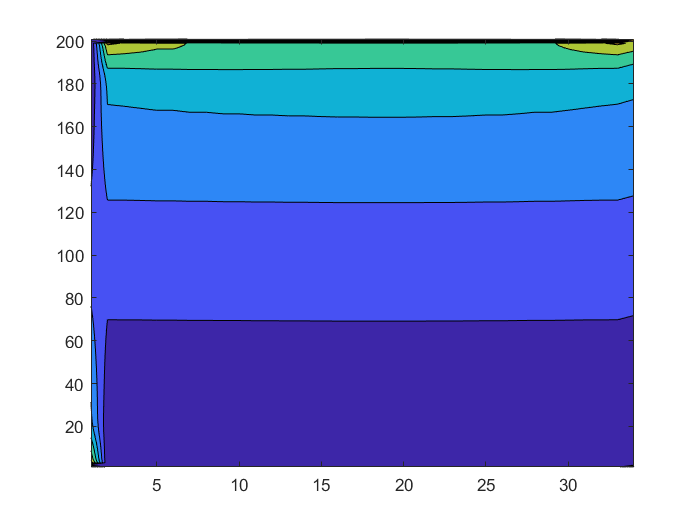

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)>0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
[~,i2y,~] = unique(round(y2,4));
[~,i2x,~] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1));
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n) = p2(g);
end
Pmap;
contourf(Pmap)

clear

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)<0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
[y2r,i2y,yi] = unique(round(y2,4));
[x2r,i2x,xi] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1));
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n) = p2(g);
end
Pmap;
contourf(Pmap)

clear